% --- Steady-State Error Analysis Script (with PDF) ---
clc; clear; close all;

% Load data
filename = "C:\Users\Markus\Dropbox\Uni\6. Semester\Bachelorprojekt\Bachelorprojekt\No wheel osscilations\control_log15.csv";
data = readtable(filename);

% Extract relevant columns
time = data.Time;
e0 = data.e0;
v_l = data.v_l;
v_r = data.v_r;

% Filter: keep only rows with activity
non_zero_mask = ~(v_l == 0 & v_r == 0 & data.u0 == 0 & e0 == 0);
time = time(non_zero_mask);
e0 = e0(non_zero_mask);

% Reset time to start at 0
time = time - time(1);

% Reference value
ref = 0.2;

% Define analysis window: from first time e0 >= 0.2 up to t = 15 s
start_idx = find(e0 >= ref, 1, 'first');
end_idx = find(time <= 15, 1, 'last');
analysis_mask = false(size(e0));
if ~isempty(start_idx) && end_idx > start_idx
    analysis_mask(start_idx:end_idx) = true;
end

% Compute steady-state error
e_analysis = e0(analysis_mask);
mean_error = mean(e_analysis);
ess_percent = (1 - mean_error / ref) * 100;

% Display stats
fprintf('Mean Error = %.4f m\n', mean_error);

Mean Error = 0.2217 m


fprintf('Relative Steady-State Error = %.2f %%\n',  ess_percent);

Relative Steady-State Error = -10.85 %


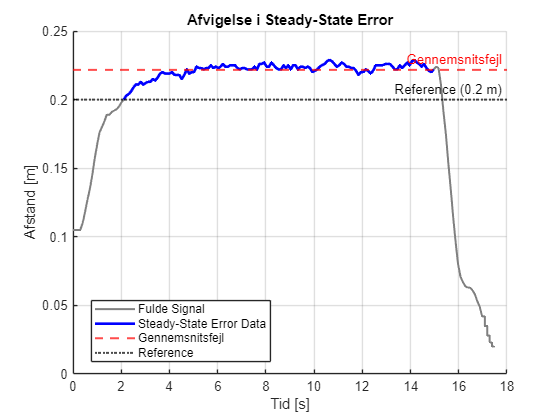


% --- Plot Error Signal ---
figure;
hold on;
plot(time, e0, 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5); % full signal in gray
plot(time(analysis_mask), e_analysis, 'b', 'LineWidth', 2); % analysis segment in blue
yline(mean_error, 'r--', 'Gennemsnitsfejl', 'LineWidth', 1.5);
yline(ref, 'k:', 'Reference (0.2 m)', 'LineWidth', 1.5);
xlabel('Tid [s]');
ylabel('Afstand [m]');
title('Afvigelse i Steady-State Error');
legend('Fulde Signal', 'Steady-State Error Data', 'Gennemsnitsfejl', 'Reference', 'Location', 'best');
grid on;

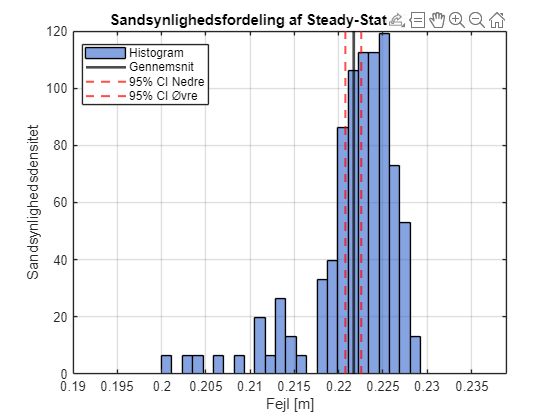


% --- Bootstrap 95% confidence interval for mean error ---
nBoot = 10000;  % number of bootstrap samples
boot_means = bootstrp(nBoot, @mean, e_analysis);  % bootstrap mean samples

% Compute 95% confidence interval
ci_95 = prctile(boot_means, [2.5 97.5]);


% --- Plot PDF of Error in Analysis Window + Mean and 95% CI ---
figure;
% Determine number of bins
num_bins = max(25, round(sqrt(length(e_analysis))));

% Plot histogram
histogram(e_analysis, num_bins, ...
    'Normalization', 'pdf', ...
    'FaceColor', [0.2 0.4 0.8], ...
    'EdgeColor', 'k');
hold on;

% Add vertical line for mean
xline(mean_error, 'k-', 'LineWidth', 2, 'DisplayName', 'Mean');

% Add vertical lines for 95% CI
xline(ci_95(1), 'r--', 'LineWidth', 1.5, 'DisplayName', '95% CI Lower');
xline(ci_95(2), 'r--', 'LineWidth', 1.5, 'DisplayName', '95% CI Upper');

% Adjust axis
xlim([min(e_analysis) - 0.01, max(e_analysis) + 0.01]);
xlabel('Fejl [m]');
ylabel('Sandsynlighedsdensitet');
title('Sandsynlighedsfordeling af Steady-State Error Data');
legend('Histogram', 'Gennemsnit', '95% CI Nedre', '95% CI Øvre', 'Location', 'best');
grid on;